# Ejercicio 5 (2 puntos). 

### Considere el modelo “robot_5DoF_entregable_R2021a.slx” que tiene disponible en aula virtual. En él se ha implementado un control de posición para la primera articulación de un robot manipulador que no se comporta correctamente.

#### a) Obtenga un modelo aproximado para el sistema de control en lazo cerrado que ya está implementado (1 pto).

Primero necesitamos crear un modelo aproximado para la planta en lazo abierto. Para ello estudiamos la respuesta de la planta ante una entrada conocida, en este caso un escalon unitario.

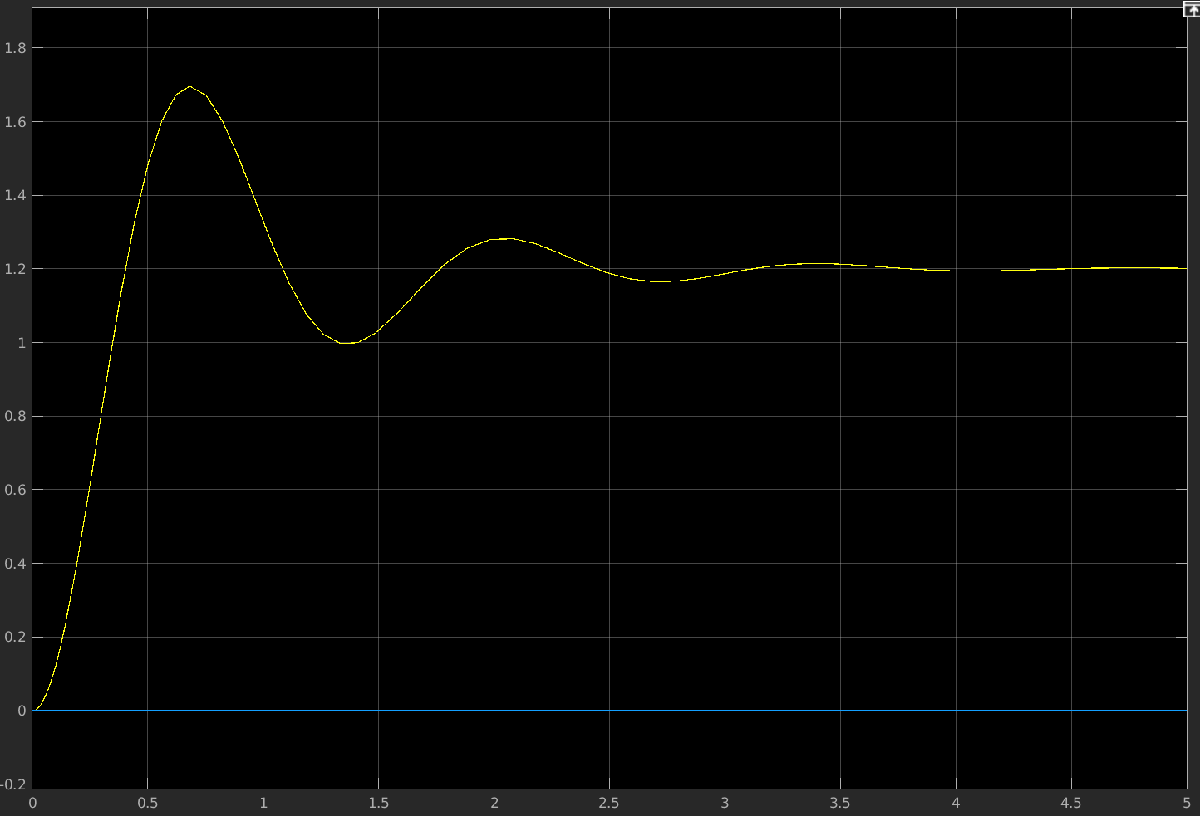

K = 1.2; % La ganancia es 1.2 porque el valor estacionario es 1.2 ante un entrada de amplitud 1
T_peak = 0.7024;
T_ris = 0.409;
Max_peak = 1.6945;
M_p = (1.6945 / 1.200) - 1 % Calculamos el porcentaje de overshoot

M_p = 0.4121

A partir de los valores conocidos, creamos el modelo de la planta usando de base uno de segundo grado. Luego:

% Calculamos wd
w_d = pi/T_peak

w_d = 4.4727


% Calculamos chi
syms chi
f = M_p == exp(-((chi*pi)/(sqrt(1-chi*chi))))

$$f = \frac{989}{2400}={\mathrm{e}}^{-\frac{\pi \,\chi }{\sqrt{1-\chi^{2}}}}$$

simplify(solve(f, chi))

$$ans = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\log\left(\frac{989}{2400}\right)\,\sqrt{\left(\log\left(\frac{989}{2400}\right)+\pi \,\mathrm{i}\right)\,\left(\log\left(\frac{2400}{989}\right)+\pi \,\mathrm{i}\right)}\,\mathrm{i}}{\pi^{2}-2\,\log\left(989\right)\,\log\left(2400\right)+{\log\left(989\right)}^{2}+{\log\left(2400\right)}^{2}} \end{array}$$

pos_chi = vpa(ans)

$$pos\_chi = \left(\begin{array}{c} 0.27158486574532798294516057430966\\ -0.27158486574532798294516057430966 \end{array}\right)$$


% Elegir solo el chi positivo de cualquiera de los 2, porque si no el
% sistema seria inestable
simplify((pi - acos(pos_chi(1)))/w_d)

$$ans = 0.41269354889600870190067879370551$$


% Calculamos wn
w_n = w_d/(sqrt(1 - pos_chi(2)*pos_chi(2)))

$$w\_n = 1.4792900688989640642784621748447\,\pi$$


% Calculamos la funcion de transferencia
g_den = [1,2*pos_chi(1)*w_n,w_n*w_n]

$$g\_den = \left(\begin{array}{ccc} 1 & 0.80350558952064427456037994234625\,\pi & 2.188299107943101848360221751987\,\pi^{2} \end{array}\right)$$

g_num = K*w_n*w_n

$$g\_num = 2.6259589295317222180322661023845\,\pi^{2}$$

Con esto defino la funcion de transferencia en lazo abierto G. Este paso es necerio, ya que sino step da error

G = tf(2.626*pi*pi, [1 0.8*pi 2.19*pi*pi])

G =
 
          25.92
  ---------------------
  s^2 + 2.513 s + 21.61
 
Continuous-time transfer function.
Model Properties


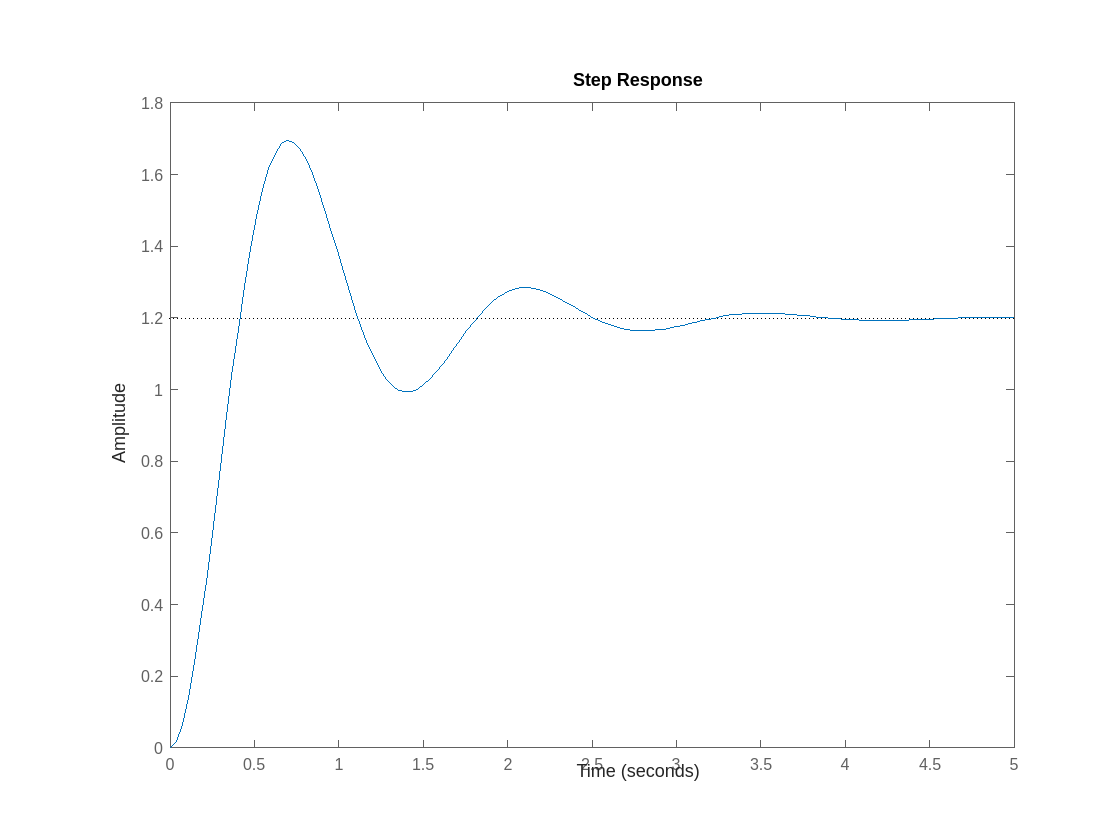

step(G)

stepinfo(G)

ans = struct with fields:
         RiseTime: 0.2776
    TransientTime: 2.9988
     SettlingTime: 2.9988
      SettlingMin: 0.9939
      SettlingMax: 1.6953
        Overshoot: 41.3820
       Undershoot: 0
             Peak: 1.6953
         PeakTime: 0.6963


Como se puede ver en las dos imagenes la respuesta es muy similar la una a la otra, por lo tanto podemos decir que hemos obtenido la representacion de la planta en lazo abierto. Ahora para conseguir el modelo en lazo cerrado realizamos un bucle de realimentacion unitario y observamos su respuesta ante la entrada escalon unitario.

% El modelo aproximado del sistema en lazo cerrado con feedback unitario
G_lc = feedback(G,1)

G_lc =
 
          25.92
  ---------------------
  s^2 + 2.513 s + 47.53
 
Continuous-time transfer function.
Model Properties


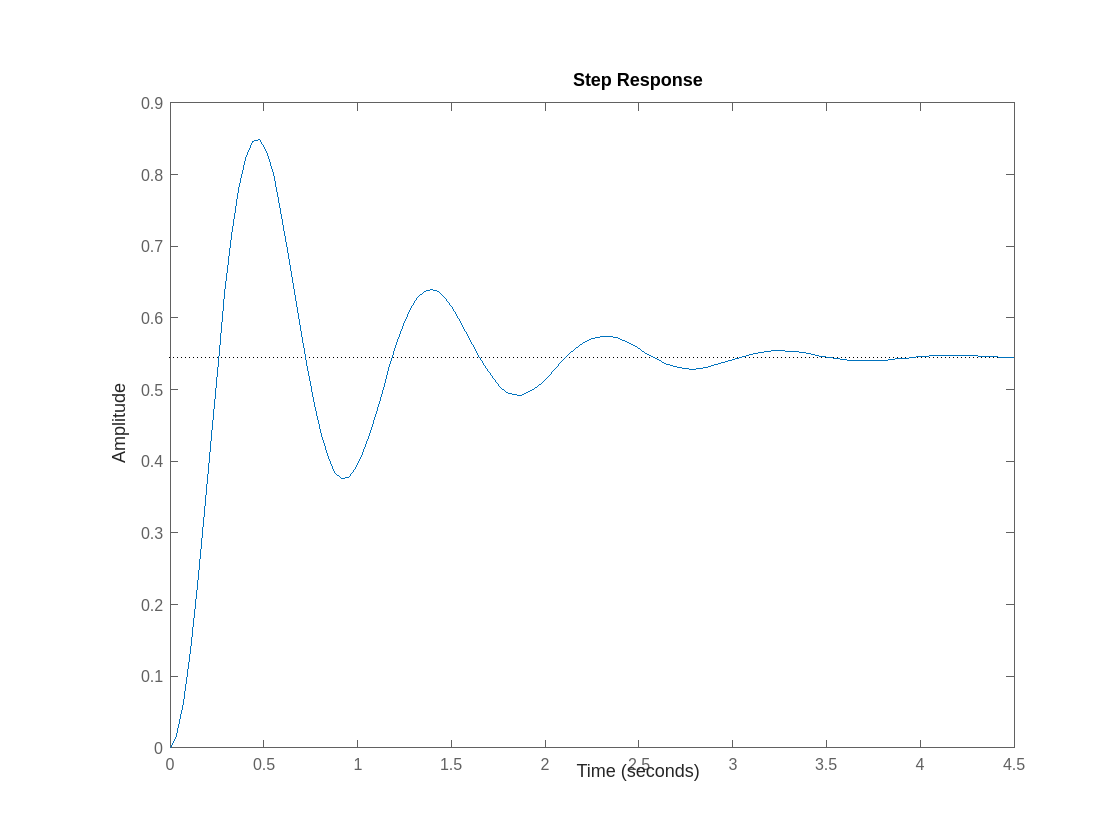

step(G_lc)

stepinfo(G_lc)

ans = struct with fields:
         RiseTime: 0.1735
    TransientTime: 2.9107
     SettlingTime: 2.9107
      SettlingMin: 0.3756
      SettlingMax: 0.8486
        Overshoot: 55.6363
       Undershoot: 0
             Peak: 0.8486
         PeakTime: 0.4764


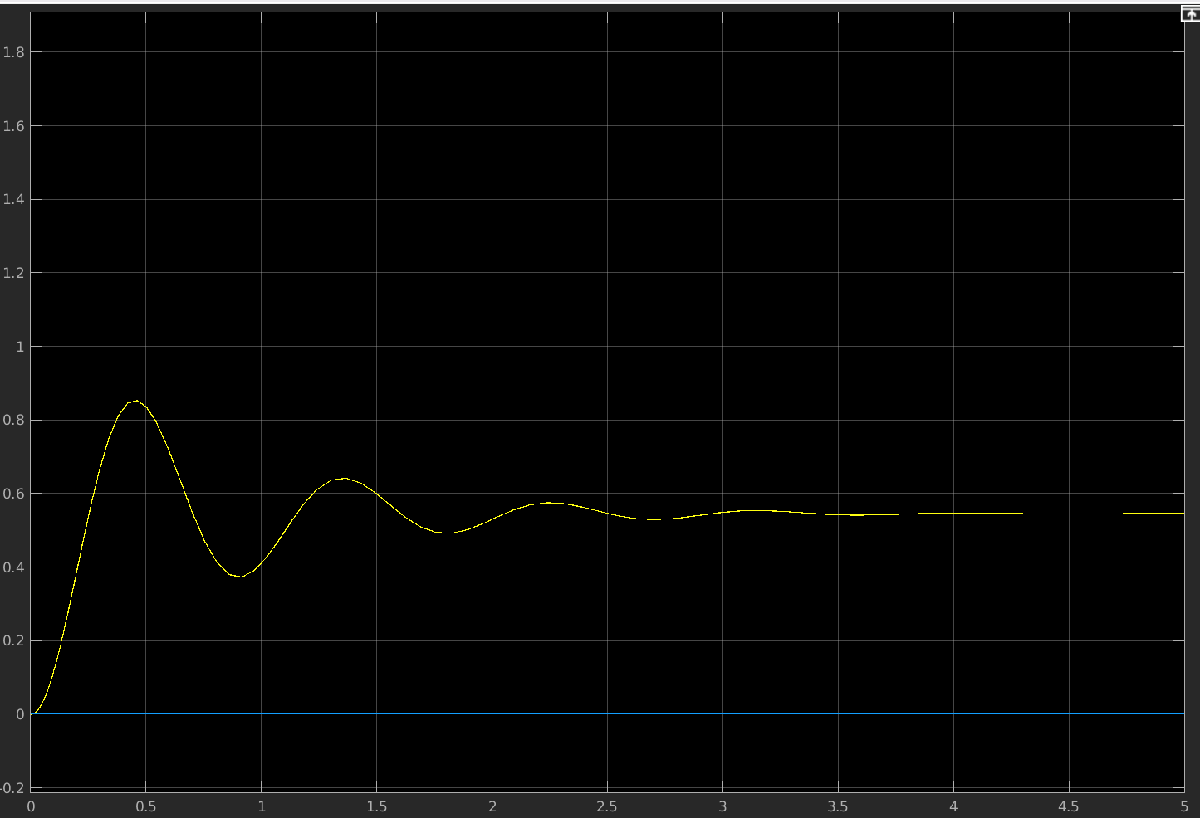

Y al igual que en lazo abierto, la respuesta se asemeja bastante a la de la planta original.

#### b) Diseñe e implemente un sistema de control realimentado para controlar la posición de la primera articulación del robot manipulador. Utilice un controlador de la familia de los PID que anule el error en estado estacionario, reduzca el tiempo de asentamiento a menos de 0.75s y la máxima sobreoscilación a menos del 10%. Simule dicho controlador sobre el modelo original del robot y analice su funcionamiento (1pto)

El PID ha sido diseñado en Simulink como se puede ver en las imagenes posteriores:

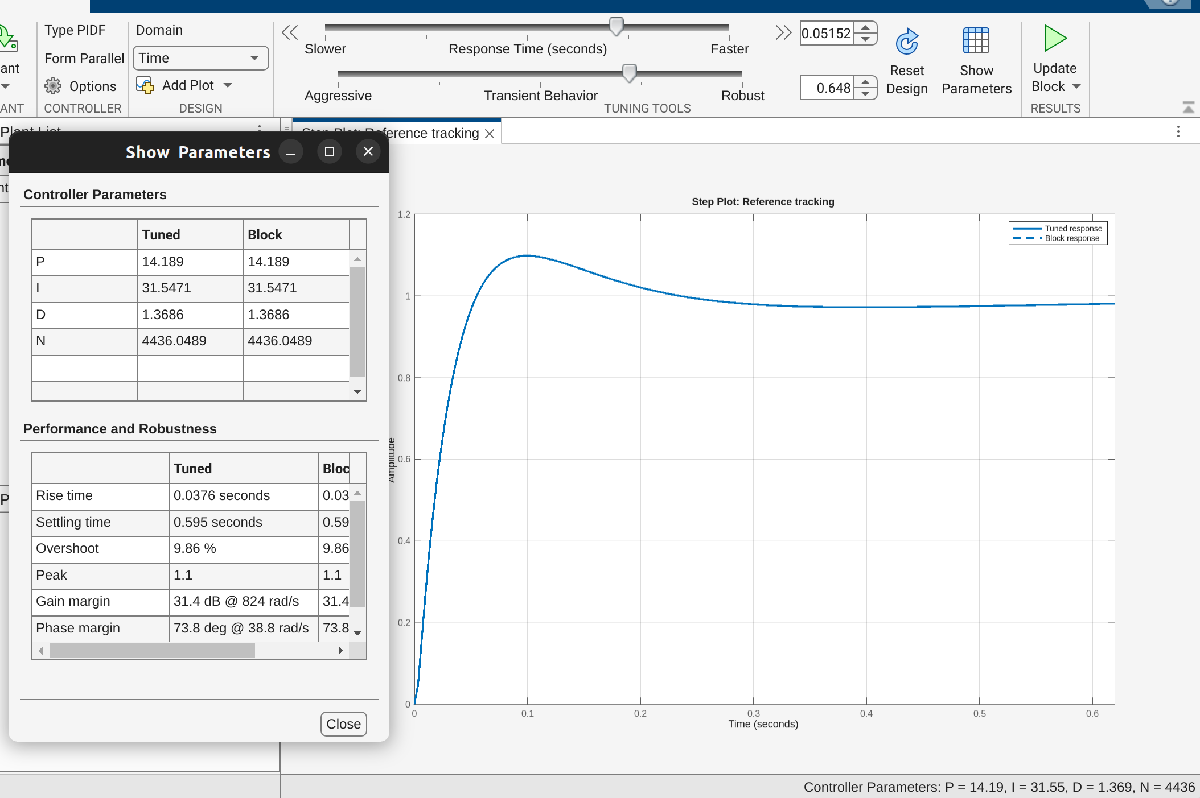

Para ver el fichero de Simulink es el ej5.slx. Para que funcione hay que seguir los pasos usados en la practica de Simulink.

En cuanto a la respuesta despues de añadir este PID, se observa que el error estacionario a desaparecido, luego tambien se aprecia que el tiempo de asentamiento es mucho menor que anteriormente (un par de segundos menos) y por ultimo la sobreooscilacion es casi minima, solo con un pequeño overshoot al principio.

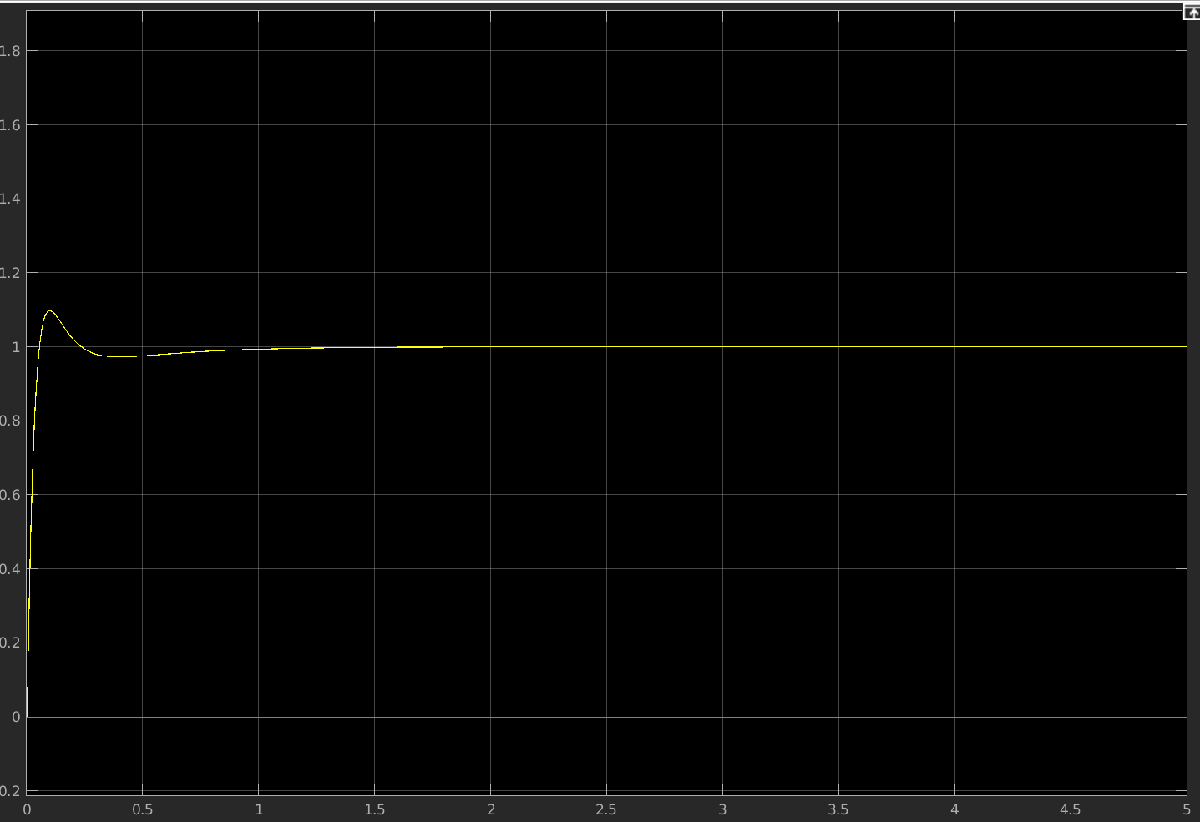

Al ver el funcionamiento de este controlador en el modelo del robot, se ve que no tarda casi tiempo en ir a la posicion final, siendo necesario bajar la velocidad para verlo en correcto funcionamiento.